clc;clear all; close all;

Read image data

imds = imageDatastore('image', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

Divid dataset

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.8,'randomized');

show part of images

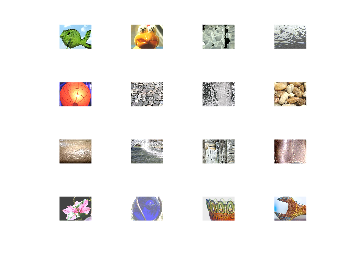

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

use googlenet pre-trained model 

net = googlenet;

design the googlenet 

deepNetworkDesigner(net)

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


lgraph = layerGraph(net); 

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 10

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
    
lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

pixelRange = [-60 60];
imageAugmenter = imageDataAugmenter( "RandRotation", [-45  45],'RandScale',[0.5 1.5],...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, "ColorPreprocessing",'gray2rgb',...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',64, ...
    'MaxEpochs',25, ...
    'InitialLearnRate',0.001, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'Plots','training-progress');

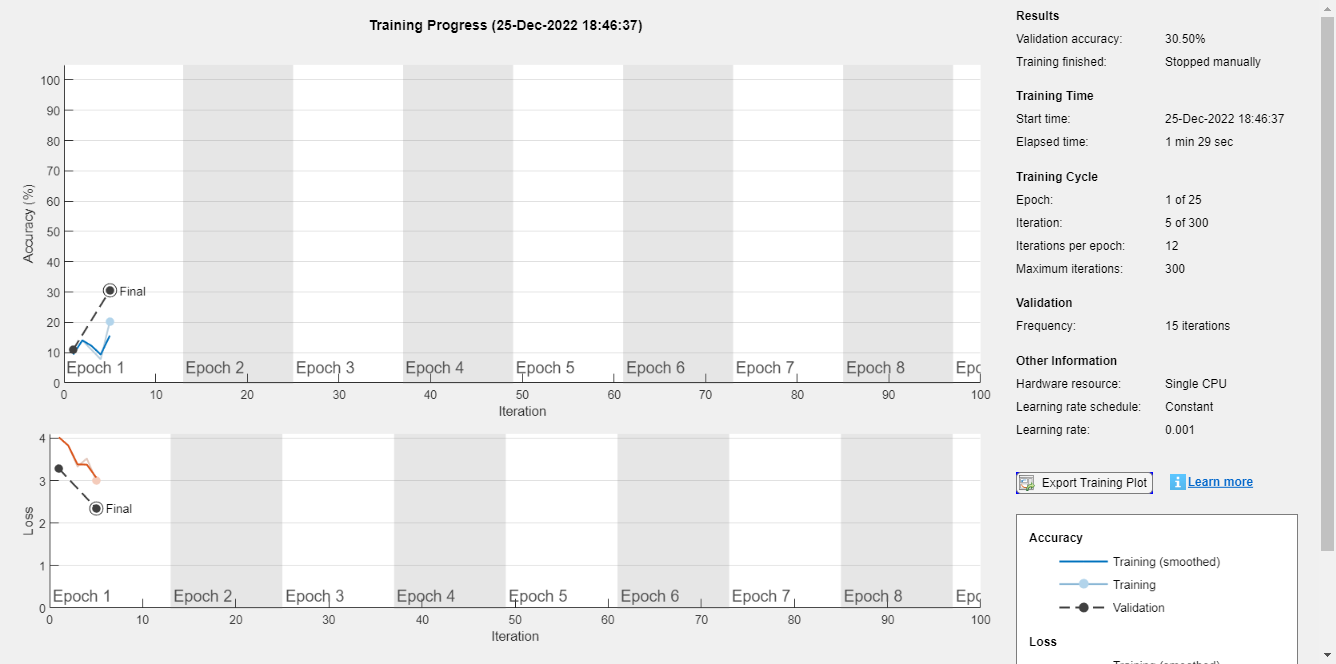

netTransfer = trainNetwork(augimdsTrain,lgraph,options);

[YPred,scores] = classify(netTransfer,augimdsValidation);

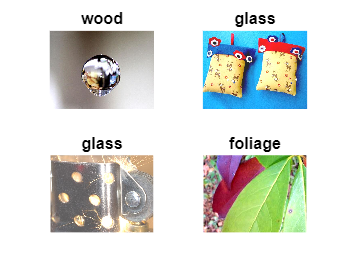

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.3050

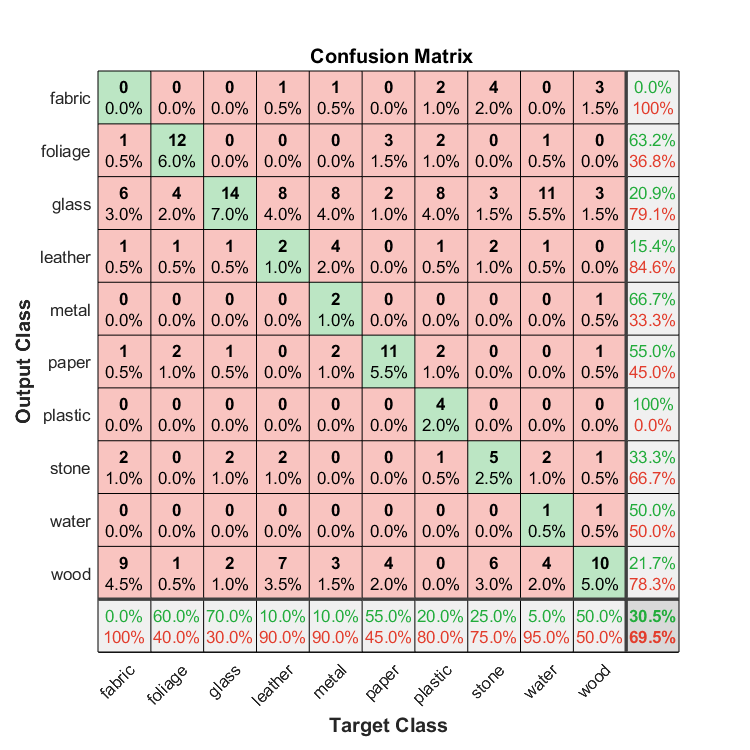


plotconfusion(YValidation,YPred)